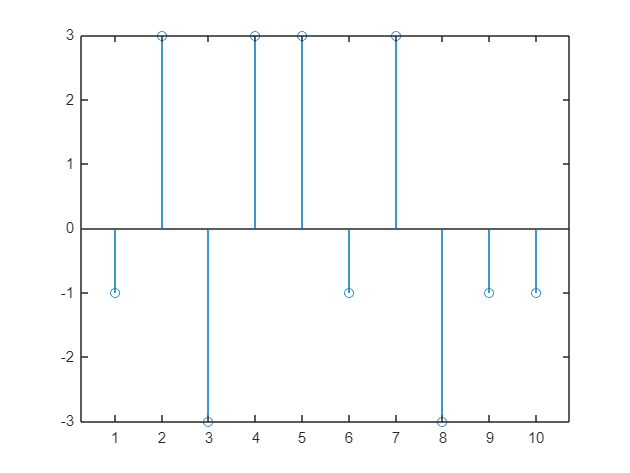

%% 1 SYMBOLS AND SINC-PULSE

%% 1.1 Generation of symbols
% useful functions: randi, stem
% YOUR CODE HERE:
alphabet = [-3 -1 1 3];
%alphabet = [-7 -5 -3 -1 1 3 5 7]; % Alphabet for 8-PAM 
N_symbols = 10;
symbol_ind = randi(length(alphabet),1,N_symbols);
symbols = alphabet(symbol_ind);
figure
stem(symbols); % Plots the symbol sequence

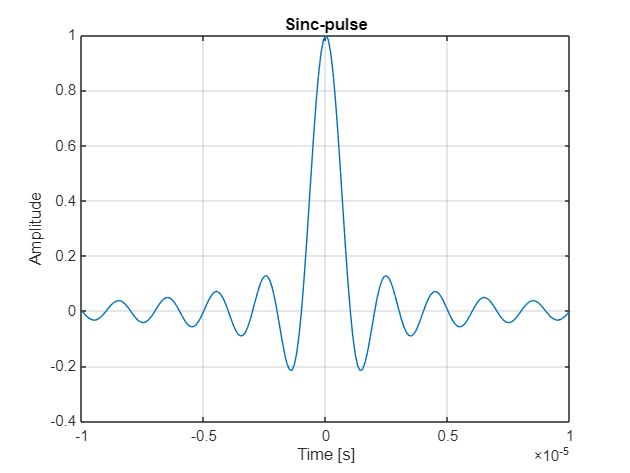


%% 1.2 Illustration of a baseband signal by using sinc-pulses
% useful functions: sinc, plot
% YOUR CODE HERE:
r=10;
T=1e-6;
Fs=r/T;
Ts=1/Fs;
t = 0:Ts:N_symbols*T;

p = @(t) sinc(t/T);

t_plot = -10e-6:Ts:10e-6;  
figure 
plot(t_plot,p(t_plot)) 
xlabel('Time [s]') 
ylabel('Amplitude') 
grid on 
xlim([-10e-6 10e-6]) 
title('Sinc-pulse')

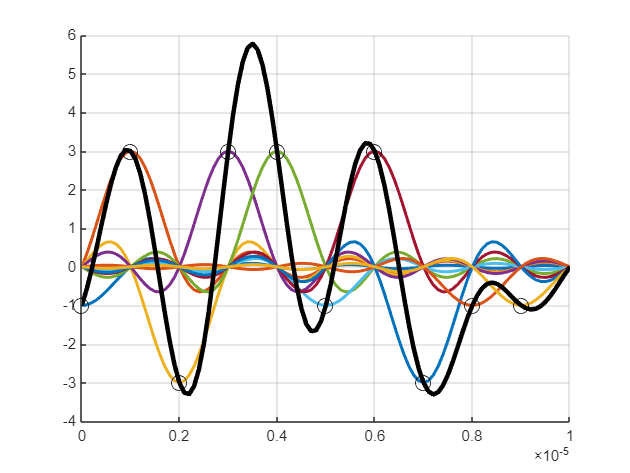

figure 
hold on
x = 0;  
a = symbols; 

for k = 0:N_symbols-1
    kth_pulse = a(k+1)*p(t-k*T);  
    x = x + kth_pulse; % add the kth pulse to the overall sum (PAM signal) 
    plot(t,kth_pulse,'LineWidth',2)  
     
end 
plot(t,x,'k','LineWidth',3) % Plotting the total signal x with black color 
 
plot(0:T:T*(N_symbols-1),symbols(1:N_symbols),'ko','MarkerSize',10) 
hold off 
grid on 

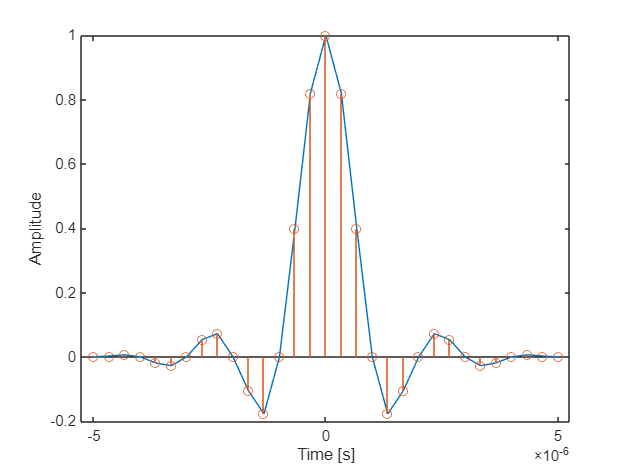


% In order to recover the transmitted symbols, we should take samples from
% the PAM signal by every Ts (i.e. sample time interval)


%% 2 BASEBAND SIGNAL BY USING A RAISED-COSINE PULSE

r = 3;              
T = 1e-6;          
 
Fs = r/T;           
Ts = 1/Fs; 

t = -5*T:Ts:5*T;  
alfa = 0.3;  
 
N_symbols = 500;
symbol_ind = randi(length(alphabet),1,N_symbols);
symbols = alphabet(symbol_ind);

p = sinc(t/T).*((cos(alfa*pi*t/T))./(1-((2*alfa*t/T).^2)));  
figure 
plot(t,p) 
hold on 
stem(t,p) 
xlabel('Time [s]') 
ylabel('Amplitude') 
hold off 

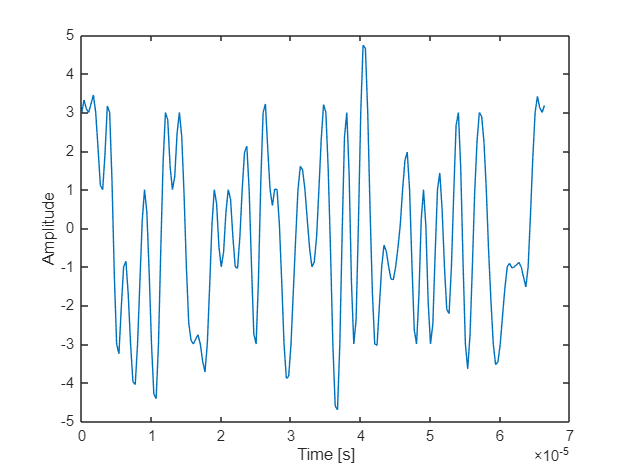

symbol_upsampled = zeros(size(1:r*N_symbols));  
symbol_upsampled(1:r:r*N_symbols) = symbols;  
xn = filter(p,1,symbol_upsampled);                 

filter_delay = (length(p)-1)/2; 
xn = xn(filter_delay+1:end); 
figure 
plot(0:Ts:199*Ts,xn(1:200)); 
xlabel('Time [s]') 
ylabel('Amplitude') 

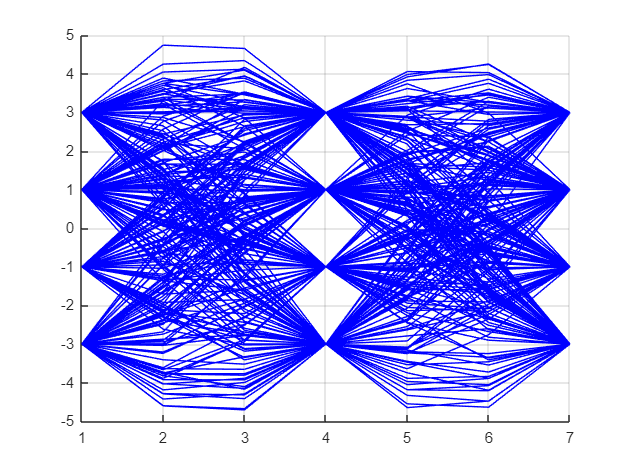



%% 3 EYE-DIAGRAM AND SPECTRAL CONSIDERATIONS

%% 3.1 Plotting the eye diagram

figure 
hold on 
for i = 1:2*r:(length(xn)-2*r) 
    plot(xn(i:i+2*r),'b'); 
end   
hold off 
grid on 

SNR_target = 20;  
zn = randn(size(xn));      
P_xn = var(xn);              
P_zn = var(zn);              
noise_scaling_factor = sqrt(P_xn/P_zn/10^(SNR_target/10)); 
%Noisy signal 
yn = xn + noise_scaling_factor*zn; 
 
P_zn_scaled = var(noise_scaling_factor*zn);  
SNR_check = 10*log10(P_xn/P_zn_scaled) 

SNR_check = 20.0000

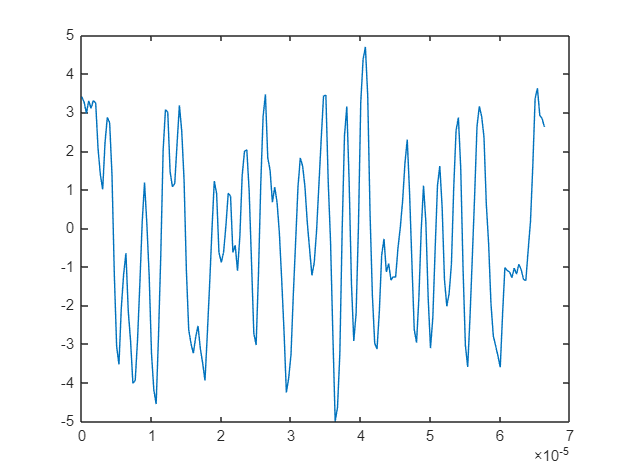


plot(0:Ts:199*Ts,yn(1:200))

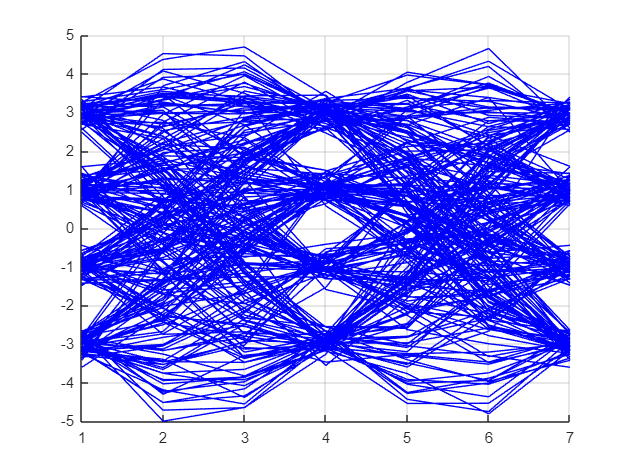

figure 
hold on 
for i = 1:2*r:(length(yn)-2*r) 
    plot(yn(i:i+2*r),'b'); 
end   
hold off 
grid on 

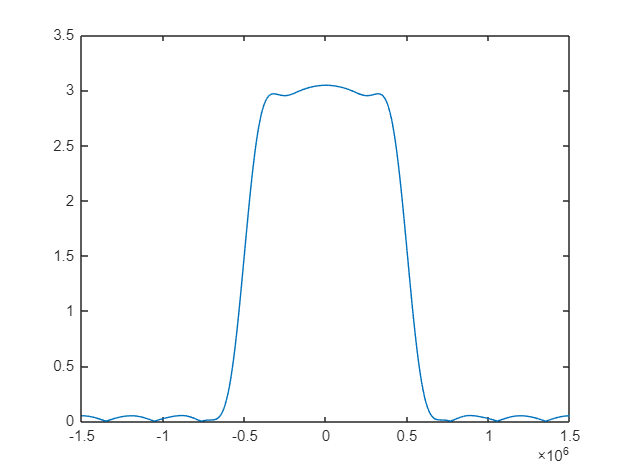


%In the noiseless eye diagram, the eye opening is clear, but in the noisy eye diagram, the eye opening is 
% narrower and more cluttered, and there are more overlapping in the transitions.

%% 3.2 Signal spectrum and pulse spectrum

FFT_size = 2048;
P_f = fftshift(abs(fft(p,FFT_size)));

Fo=Fs/FFT_size; 
freq=-2048/2*Fo:Fo:(2048/2-1)*Fo; 
figure 
plot(freq,P_f) % Two-sided amplitude Spectrum

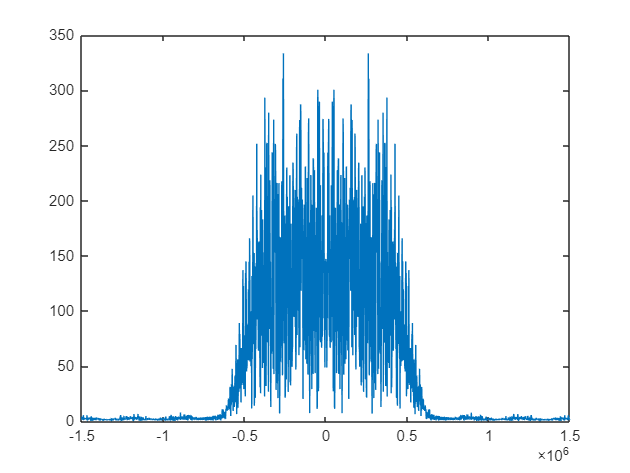

plot(freq,fftshift(abs(fft(xn,FFT_size))))

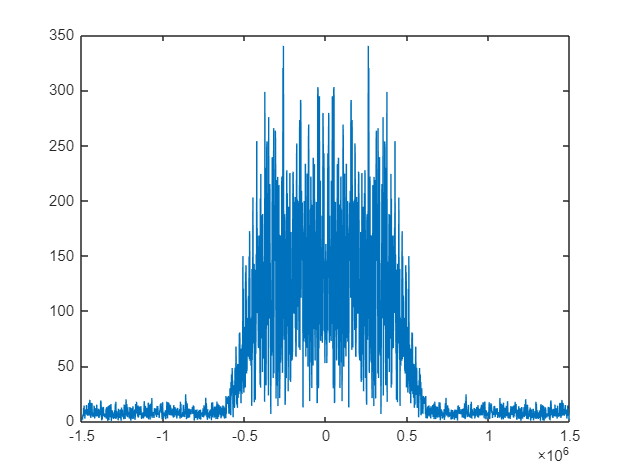

plot(freq,fftshift(abs(fft(yn,FFT_size))))

% Comparing the pulse spectrum and the PAM signal spectra, we can see that
% they have similar bandwidth.

%% 3.3 Modifying the system parameter


%When using 8-PAM, the pulse shape is quite similar to using the 4-PAM
%symbol. The eye diagram looks denser, and it is harder to intepret the
%transitions. The spectrum and bandwidth of the signals are similar.


%When changing the system's SNR to 15dB and 10dB, the pulse shape and
%spectrum are do not undergo much change. The eye diagram of the noisy
%signal is messy since the eye opening is greatly reduced.

%Whe changing the roll-off alpha, the pulse shape amplitude is changed
%everywhere except for around 0. The eye diagrams have a clearer
%transitions, and the spectrum of the signals have a parabolic shape for
% large alpha, and have more ripples for small alpha 